clc;clear;

% 打开原文件和新文件
fid_in = fopen('.\Data\ev_CFO\CFO4.log', 'r');
fid_out = fopen('.\Data\ev_CFO\CFO4.txt', 'w');
% 循环读取每一行

while ~feof(fid_in)
    line = fgetl(fid_in);  % 读取一行
    % 判断并删除开头的 '00>'（含空格）
    if startsWith(line, '00> ')
        line = extractAfter(line, '00> ');
    elseif startsWith(line, '00>')
        line = extractAfter(line, '00>');
    end
    % 写入新文件
    fprintf(fid_out, '%s\n', line);
end

% 关闭文件
fclose(fid_in);
fclose(fid_out);

disp('处理完成！');

处理完成！


% 读取CFO2.txt文件并提取ppm值
fid = fopen('.\Data\ev_CFO\CFO4.txt', 'r');
if fid == -1

    error('无法打开文件CFO2.txt');
end

ppm_values = [];
while ~feof(fid)
    line = fgetl(fid);
    % 检查行是否包含'Clock Offset'
    if contains(line, 'Clock Offset')
        % 使用正则表达式提取ppm值（包括负号）
        tokens = regexp(line, '[-]?\d+\.\d+ ppm', 'match');
        if ~isempty(tokens)
            % 提取数字部分
            num_str = regexp(tokens{1}, '[-]?\d+\.\d+', 'match');
            ppm_val = str2double(num_str{1});
            ppm_values = [ppm_values, ppm_val];
        end
    end
end
fclose(fid);


% 计算平均值和标准差
mean_ppm = mean(ppm_values);
std_ppm = std(ppm_values);

% 显示结果
fprintf('提取的ppm值: \n');

提取的ppm值: 


disp(ppm_values);

  列 1 至 14

   -0.6540   -0.7860   -0.7360   -0.7450   -0.6850   -0.7860   -0.6760   -0.7010   -0.6360   -0.7070   -0.7710   -0.7510   -0.7190   -0.6790

  列 15 至 28

   -0.7810   -0.6720   -0.7550   -0.8220   -0.7270   -0.8160   -0.7590   -0.7660   -0.6090   -0.7010   -0.8070   -0.6270   -0.7110   -0.7950

  列 29 至 42

   -0.7190   -0.8440   -0.6850   -0.7970   -0.7140   -0.7220   -0.7590   -0.6700   -0.6460   -0.7120   -0.8010   -0.8090   -0.6330   -0.6840

  列 43 至 56

   -0.8430   -0.7330   -0.6770   -0.6890   -0.7570   -0.6970   -0.7270   -0.7490   -0.8910   -0.8970   -0.6730   -0.7280   -0.8410   -0.7070

  列 57 至 70

   -0.7710   -0.8220   -0.9360   -0.6290   -0.8010   -0.7250   -0.5930   -0.6710   -0.6570   -0.7390   -0.7440   -0.6480   -0.8290   -0.8010

  列 71 至 84

   -0.5560   -0.6410   -0.7410   -0.7550   -0.6480   -0.6970   -0.7530   -0.5350   -0.7800   -0.7550   -0.6990   -0.7170   -0.7140   -0.7970

  列 85 至 98

   -0.7790   -0.7200   -0.6590   -0.7780   -0.6630   -0.61

fprintf('ppm平均值: %.3f\n', mean_ppm);

ppm平均值: -0.736


fprintf('ppm标准差: %.3f\n', std_ppm);

ppm标准差: 0.077


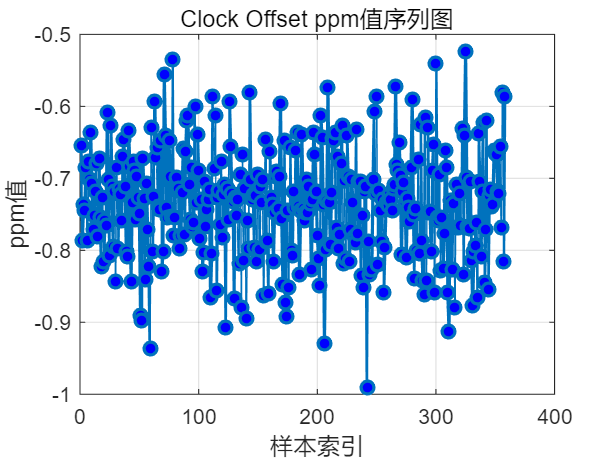


% 绘制折线图
figure;
plot(ppm_values, 'o-', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
xlabel('样本索引');
ylabel('ppm值');
title('Clock Offset ppm值序列图');
grid on;

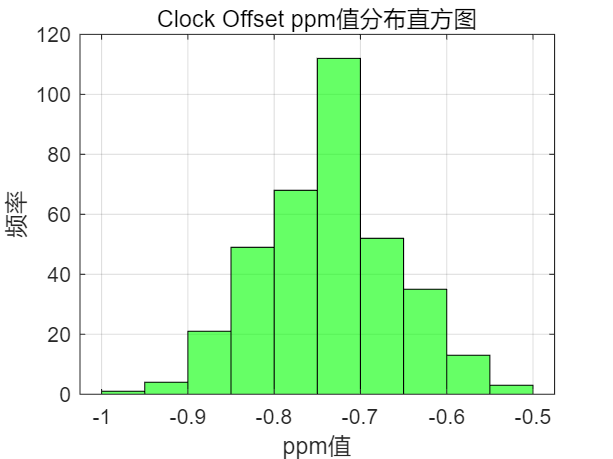


% 绘制直方图
figure;
histogram(ppm_values, 'BinWidth', 0.05, 'FaceColor', 'g');
xlabel('ppm值');
ylabel('频率');
title('Clock Offset ppm值分布直方图');
grid on;

% 读取文本文件
filename = '.\Data\AODview45\AODr45_l15.txt';  % <-- 改成你的文件名
fid = fopen(filename, 'r');
rawData = textscan(fid, '%s', 'Delimiter', '\n');

错误使用 textscan
文件标识符无效。使用 fopen 生成有效的文件标识符。

fclose(fid);

% 获取行内容
lines = rawData{1};


% 初始化存储变量
sn_len = [];
% CIR存储结构
Ipatov_CIR = [];
STS0_CIR = [];
STS1_CIR = [];

% 状态标志
current_mode = '';   % 当前是哪种CIR类型（Ipatov / STS0 / STS1）
inside_CIR_block = false;  % 是否正在读取CIR数据

% 遍历每一行，按规则提取
for i = 1:length(lines)
    line = strtrim(lines{i});
    
    if contains(line, 'Sequence Number')
        tokens = regexp(line, 'Sequence Number[:\s]+(\d+)', 'tokens');
        if ~isempty(tokens)
            sn_len = [sn_len, str2double(tokens{1}{1})];
        else
            disp(['Regex failed to match: ', line]);  % 调试用
        end
    end
        
    
 % 检测 CIR 类型标志
    if contains(line, 'Printing Ipatov CIR')
        current_mode = 'Ipatov';
        inside_CIR_block = false;  % 等待进入“-----------”段

        
    elseif contains(line, 'Printing STS0 CIR')
        current_mode = 'STS0';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS1 CIR')
        current_mode = 'STS1';
        inside_CIR_block = false;  % 等待进入“-----------”段 
    end
    
    % 检测 “-----------” 的起始和结束
    if contains(line, '_________________________________')
        inside_CIR_block = ~inside_CIR_block;  % 切换状态
        continue;  % 这行不用处理
    end
    
    % 正在 CIR 数据块内，提取 I, Q
    if inside_CIR_block
        data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
        if ~isempty(data_tokens)
            I_val = str2double(data_tokens{1}{1});
            Q_val = str2double(data_tokens{1}{2});
            complex_val = I_val + 1j * Q_val;
            % 根据当前模式放入不同数组
            if strcmp(current_mode, 'Ipatov')
                Ipatov_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS0')
                STS0_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS1')
                STS1_CIR(end+1, 1) = complex_val;
            end
        end
    end
end

% 输出到命令行确认
disp(['Sequence Number: ', num2str(sn_len)]);

packets_num = floor(length(STS0_CIR)/512);  % 向下取整，确保能reshape成功
STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';

% 如果 packets_num 是奇数，丢弃最后一行
if mod(packets_num, 2) ~= 0
    STS0_CIR(end, :) = [];
    STS1_CIR(end, :) = [];
    packets_num = packets_num - 1 ;
end

c =physconst("LightSpeed"); % wavelength (assume)
% lambda=c/4992.8e6;
lambda=c/7.9872e9;
antennaSpacing = lambda * 0.5;
% antennaSpacing = 0.0182;
% frequency=4992.8e6;
frequency=7.9872e9;
phase_offset = 0.17;
% -0.67, -0.88, -1.01， -0.72


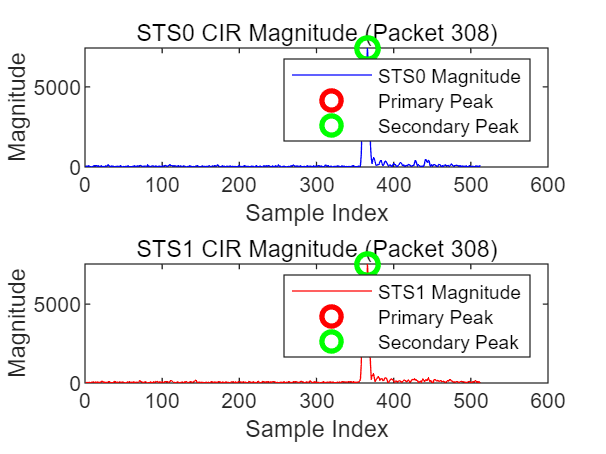

aoa_pdoa_values_main = [];
aoa_degree_values_main = [];

aoa_pdoa_values_secondary = [];
aoa_degree_values_secondary = [];

peaks_index_STS0 = [];
peaks_index_STS1 = [];

for i = 1:packets_num
    % i =2 ;
    % 取出第 i 组 CIR 数据
    STS0_data = STS0_CIR(i,:);  %首先进行了分行的操作
    STS1_data = STS1_CIR(i,:);
    
    % 幅度
    STS0_magnitude = abs(STS0_data);
    STS1_magnitude = abs(STS1_data);

    threshold = 0.1;  % 阈值
    min_peak_distance = 5;  % 峰值之间最少间隔 4 个采样点
    
    % 找峰值
    [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);


    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_STS0) < 2 || length(locs_STS1) < 2
        continue; % 跳过不满足条件的帧
    end

    % 主峰和次强峰索引
    peak_index1_STS0 = locs_STS0(1);
    peak_index2_STS0 = locs_STS0(2);
    
    peak_index1_STS1 = locs_STS1(1);
    peak_index2_STS1 = locs_STS1(2);


    % 保存索引
    peaks_index_STS0 = [peaks_index_STS0; peak_index1_STS0,peak_index2_STS0];
    peaks_index_STS1 = [peaks_index_STS1; peak_index1_STS1,peak_index2_STS1];
    
    %% ---- 主峰相位差计算 ----
    STS0_phase_main = angle(STS0_data(peak_index1_STS1));
    STS1_phase_main = angle(STS1_data(peak_index1_STS1));
    phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
    phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;

    theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_main = rad2deg(theta_radians_main);

    aoa_pdoa_values_main(1,end+1) = phase_difference_main;
    aoa_degree_values_main(1,end+1) = theta_degrees_main;
    
    %% ---- 次强峰相位差计算 ----
    STS0_phase_secondary = angle(STS0_data(peak_index2_STS1));
    STS1_phase_secondary = angle(STS1_data(peak_index2_STS1));
    phase_difference_secondary = STS1_phase_secondary - STS0_phase_secondary - phase_offset;
    phase_difference_secondary = mod(phase_difference_secondary + pi, 2*pi) - pi;

    theta_radians_secondary = asin(phase_difference_secondary * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_secondary = rad2deg(theta_radians_secondary);

    aoa_pdoa_values_secondary(1,end+1) = phase_difference_secondary;
    aoa_degree_values_secondary(1,end+1) = theta_degrees_secondary;

    % ---- 画图并标记峰值 ----
    figure(100);
    clf; % 清空画布

    subplot(2,1,1);
    plot(STS0_magnitude, 'b');
    hold on;
    plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS0, STS0_magnitude(peak_index2_STS0), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS0 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS0 Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(STS1_magnitude, 'r');
    hold on;
    plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS1, STS1_magnitude(peak_index2_STS1), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS1 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS1 Magnitude', 'Primary Peak', 'Secondary Peak');
    % 
    % % 把当前帧写入视频
    % frame = getframe(gcf);
    % writeVideo(v, frame);
end

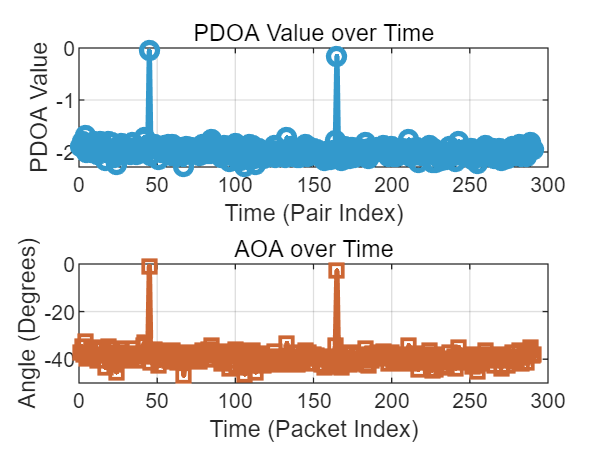

time = 1:length(aoa_pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, aoa_pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, aoa_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOA over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aoa_pdoa_values_main);
mean_degree = mean(aoa_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aoa_pdoa_values_main);
std_degree = std(aoa_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: -1.98


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 0.19



fprintf('\nmain Degree 平均值: %.2f\n', mean_degree);


main Degree 平均值: -39.09


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 3.90



mean_degree = mean(aoa_degree_values_secondary)

mean_degree = -2.9390

fprintf('\nsecondary Degree 平均值: %.2f\n', mean_degree);


secondary Degree 平均值: -2.94


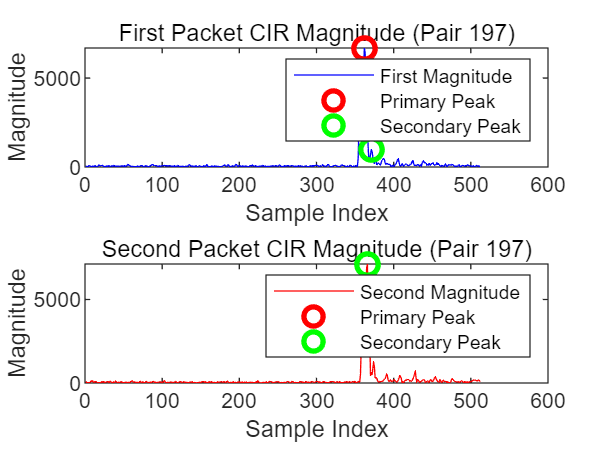

first_packet_cir  = STS0_CIR(1:2:end, :);  % 奇数行
second_packet_cir = STS0_CIR(2:2:end, :);  % 偶数行

aod_pdoa_values_main = [];
aod_degree_values_main = [];

aod_pdoa_values_secondary = [];
aod_degree_values_secondary = [];

peaks_index_first = [];
peaks_index_second = [];

% video_filename = 'AOD_3.avi';
% v = VideoWriter(video_filename);  % 默认是 Motion JPEG AVI
% v.FrameRate = 5;  % 可根据需要调整帧率
% open(v);

num_pairs = size(first_packet_cir, 1);  % 每组两个packet

for i = 1:num_pairs
    first_data = first_packet_cir(i, :);
    second_data = second_packet_cir(i, :);
    
    % 幅度
    first_magnitude = abs(first_data);
    second_magnitude = abs(second_data);

    threshold = 0.1;
    min_peak_distance = 5;
    
    [peaks_first, locs_first] = findpeaks(first_magnitude, 'MinPeakHeight', threshold * max(first_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_second, locs_second] = findpeaks(second_magnitude, 'MinPeakHeight', threshold * max(second_magnitude), 'MinPeakDistance', min_peak_distance);

    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_first) < 2 || length(locs_second) < 2
        continue; % 跳过不满足条件的帧
    end

    peak_index1_first = locs_first(1);
    peak_index2_first = locs_first(2);

    peak_index1_second = locs_second(1);
    peak_index2_second = locs_second(2);

   
    peaks_index_first = [peaks_index_first; peak_index1_first, peak_index2_first];
    peaks_index_second = [peaks_index_second; peak_index1_second, peak_index2_second];

    % ---- 主峰相位差计算 ----
    phase_first_main = angle(first_data(peak_index1_first));
    phase_second_main = angle(second_data(peak_index1_second));
    phase_diff_main = phase_second_main - phase_first_main ;
    phase_diff_main = mod(phase_diff_main + pi, 2*pi) - pi;

    theta_rad_main = asin(phase_diff_main * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_main = rad2deg(theta_rad_main);

    aod_pdoa_values_main(end+1) = phase_diff_main;
    aod_degree_values_main(end+1) = theta_deg_main;

    % ---- 次强峰相位差计算 ----
    phase_first_sec = angle(first_data(peak_index2_first));
    phase_second_sec = angle(second_data(peak_index2_second));
    phase_diff_sec = phase_second_sec - phase_first_sec;
    phase_diff_sec = mod(phase_diff_sec + pi, 2*pi) - pi;

    theta_rad_sec = asin(phase_diff_sec * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_sec = rad2deg(theta_rad_sec);

    aod_pdoa_values_secondary(end+1) = phase_diff_sec;
    aod_degree_values_secondary(end+1) = theta_deg_sec;

    % ---- 画图 ----
    figure(100);    
    clf; 
    subplot(2,1,1);
    plot(first_magnitude, 'b');
    hold on;
    plot(peak_index1_first, first_magnitude(peak_index1_first), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_first, first_magnitude(peak_index2_first), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['First Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('First Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(second_magnitude, 'r');
    hold on;
    plot(peak_index1_second, second_magnitude(peak_index1_second), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_second, second_magnitude(peak_index2_second), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['Second Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('Second Magnitude', 'Primary Peak', 'Secondary Peak');

    % frame = getframe(gcf);
    % writeVideo(v, frame);
end


% close(v);
% disp(['视频已保存为: ', video_filename]);

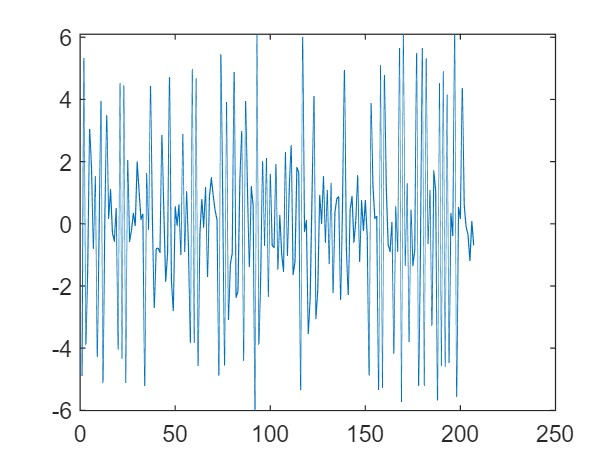

figure;
pd = diff(aod_pdoa_values_main);
plot(pd)

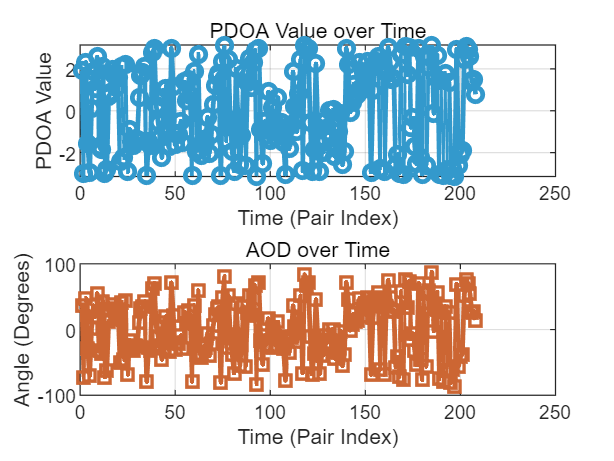

time = 1:length(aod_pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, aod_pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;


subplot(2,1,2);
plot(time, aod_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOD over Time');
xlabel('Time (Pair Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_values_main);
mean_degree = mean(aod_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_values_main);
std_degree = std(aod_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: 0.00


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 2.03



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: -0.31


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 45.06


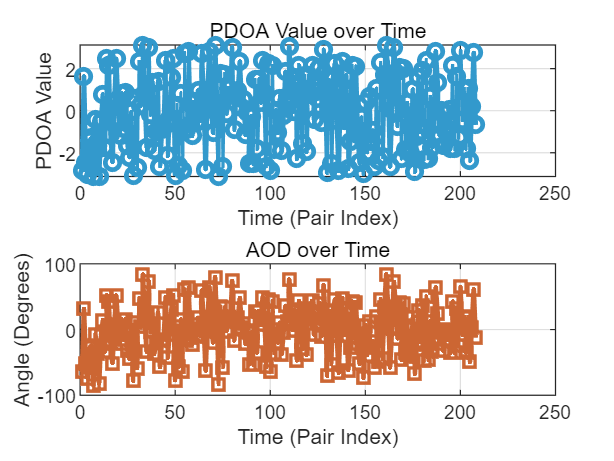

time = 1:length(aod_pdoa_values_secondary);
figure;
subplot(2,1,1);
plot(time, aod_pdoa_values_secondary, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, aod_degree_values_secondary, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOD over Time');
xlabel('Time (Pair Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_values_secondary);
mean_degree = mean(aod_degree_values_secondary);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_values_secondary);
std_degree = std(aod_degree_values_secondary);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: -0.05


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 1.81



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: -1.29


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 39.39


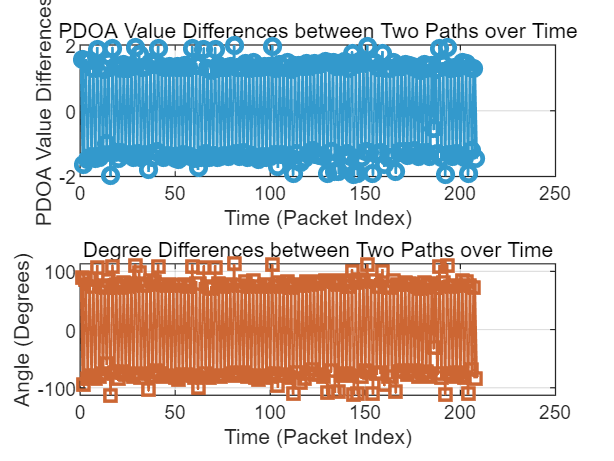

time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = mod(aod_pdoa_diff + pi, 2*pi) - pi;
%aod_pdoa_diff = abs(aod_pdoa_diff)
aod_degree_diff= asin(aod_pdoa_diff * c / (2 * pi * antennaSpacing * frequency));
aod_degree_diff = rad2deg(aod_pdoa_diff);
%aod_degree_diff = abs(aod_degree_diff)
figure;
subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences');
grid on;

subplot(2,1,2);
plot(time, aod_degree_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');

grid on;



% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_diff);
mean_degree = mean(aod_degree_diff);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_diff);
std_degree = std(aod_degree_diff);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: 0.01


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 1.45



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: 0.43


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 83.02


time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = abs(mod(aod_pdoa_diff + pi, 2*pi) - pi);

% 弧度转换为角度
aod_degree_diff = rad2deg(aod_pdoa_diff);  % 注意这里不再使用asin公式

% ----------- 滤除异常值（使用Z-score法） -------------
% 对 PDOA 进行异常值剔除
z_pdoa = abs((aod_pdoa_diff - mean(aod_pdoa_diff)) / std(aod_pdoa_diff));
valid_idx_pdoa = z_pdoa < 3;  % 3σ内为正常值
filtered_pdoa = aod_pdoa_diff(valid_idx_pdoa);

% 对 Degree 进行异常值剔除
z_degree = abs((aod_degree_diff - mean(aod_degree_diff)) / std(aod_degree_diff));
valid_idx_degree = z_degree < 3;
filtered_degree = aod_degree_diff(valid_idx_degree);

% 滤除后的时间轴（可选）
filtered_time_pdoa = time(valid_idx_pdoa);
filtered_time_degree = time(valid_idx_degree);

% ---------------- 绘图 ----------------
figure;
subplot(2,1,1);
plot(filtered_time_pdoa, filtered_pdoa, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('Filtered PDOA Value Differences over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences (rad)');
grid on;

subplot(2,1,2);
plot(filtered_time_degree, filtered_degree, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Filtered Degree Differences over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% ---------------- 输出统计量 ----------------
fprintf('--- After Filtering ---\n');

--- After Filtering ---


fprintf('PDOA 平均值: %.4f rad\n', mean(filtered_pdoa));

PDOA 平均值: 1.7255 rad


fprintf('PDOA 标准差: %.4f rad\n', std(filtered_pdoa));

PDOA 标准差: 0.0982 rad



fprintf('\nDegree 平均值: %.2f°\n', mean(filtered_degree));


Degree 平均值: 98.87°


fprintf('Degree 标准差: %.2f°\n', std(filtered_degree));

Degree 标准差: 5.63°
